## Supplemental script to "Simulation of Steady State Energy Metabolism in Cyling and Running"

### Script for creating Figure 3

*Script written (2019) and commented (2022) by Simon Nolte.*

This script requires the installation of the "Symbolic Math Toolbox".

####  Setup

clc
clearvars
close all
% Define constants
Ks1 = 0.25;
n_ox = 2;
Ks2 = 1.1;
n_la = 3;
clare = 0.1;
ratio = 100;

#### Calculate lines

syms x;
x = linspace(0, 1, 100);
nvla = (1 ./ (1+ ((Ks2 ./ Ks1 .* ((1 - x)./ x).^(1 ./ n_ox)).^ n_la)));
nvlare = ((clare .* ratio .* x) ./ 60 );
nvlare2 = 1.5 .* nvlare;
nvlare05 = (2/3) .* nvlare;

#### Create plot

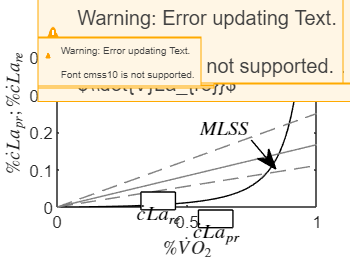

% Plot lines
plot(x,nvla,'Color','k')
hold on
plot(x,nvlare,'Color','#808080')
plot(x,nvlare2,'Color','#808080','LineStyle',"--")
plot(x,nvlare05,'Color','#808080','LineStyle',"--")

% Set labels
ylabel('$\%\dot{c}La_{pr};\%\dot{c}La_{re}$',...
    'Interpreter','latex');
xlabel('$\%\dot{V}O_{2}$',...
    'Interpreter','latex');

% Set axes
axis([0 1 0 0.5])
axis fill

% Create annotations
annotation('textarrow',[0.717857142857143 0.788095238095237],...
    [0.463492063492064 0.352380952380953],'String','$MLSS$', 'Interpreter','latex');
annotation('textbox',...
    [0.566868888125533 0.12777777126739 0.0986073023506572 0.0676378916919468],...
    'String','$\dot{c}La_{pr}$',...
    'Interpreter','latex',...
    'HorizontalAlignment','center',...
    'FitBoxToText','off',...
    'BackgroundColor',[1 1 1]);
annotation('textbox',...
    [0.402583244726771 0.196031739030566 0.0986072314637047 0.0683018412854936],...
    'String','$\dot{c}La_{re}$',...
    'Interpreter','latex',...
    'HorizontalAlignment','center',...
    'FontName','Calibri',...
    'FitBoxToText','off',...
    'BackgroundColor',[1 1 1]);
hold off

#### Write plot file

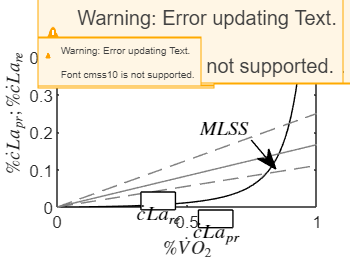

set(gcf,'PaperUnits','inches','PaperPosition',[0 0 6 4])
FigureTitle_print = strcat({'../plots/Fig3'});
path_name = fullfile('.', '..', '/plots/Fig3.png');
print(path_name,'-dpng', '-r1000');